# Eingebettete Runge-Kutta-Verfahren

Wir betrachten die Van-der-Pol-Gleichung (siehe Buch) für $t \in [0,T]$ mit $T=40$:

$ y_1'=y_2, ~~y_1(0)=y_1^0
 $ , 

$ y_2'=\mu (1-y_1^2)y_2-y_1, ~~y_2(0)=y_2^0
 $ ,

mit einem Parameter $\mu >0$. 

In diesem Matlabprogram wird die Matlab-Routine `ode45` zur numerischen Lösung dieses Anfangswertproblems verwendet.

Die `ode45`-Routine basiert auf einem  eingebetteten RK-Verfahren, wobei ein RK-Verfahren 4-ter Ordnung in ein RK-Verfahren 5-ter Ordnung eingebettet ist (das Verfahren stammt von  Dormand&Prince). Pro Zeitschritt werden 6 Funktionsauswertungen (d.h., Auswertungen der rechten Seite der Differentialgleichung) berechnet. Das Verfahren ist ähnlich zu dem im Buch  behandelten eingebetteten Runga-Kutta-Fehlberg-Verfahren RKF45.

Wir wählen den Parameter $\mu$ und setzen die Anfangsbedingungen $y_1^0$, $y_2^0$. Vernünftige Parameterwerte liegen im Bereich $\mu \in [1,40]$. 

global mu;
mu=5;
ystart=[2;0];

In der **ode45**-Routine kann die angesterbte relative Toleranz gesetzt werden (Defaultwert ist $10^{-3}$). Die berechnete Lösungskomponente $y_1(t)$ und die adaptiv bestimmte Zeitschrittweite $h_j$ werden geplottet.

relToleranz=10^-6

relToleranz = 1.0000e-06

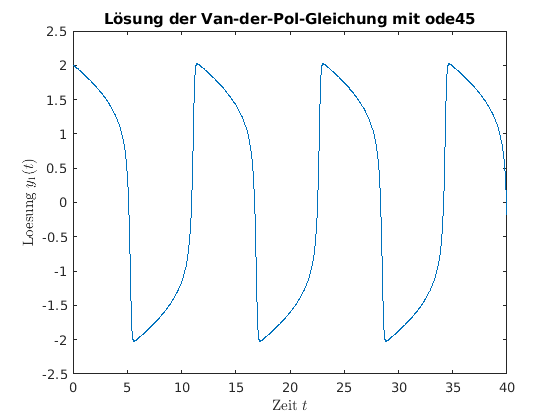

T=40;
options = odeset('RelTol',relToleranz);
[t,y] = ode45(@f,[0 T],ystart,options);

plot(t,y(:,1),'-');
title('Lösung der Van-der-Pol-Gleichung mit ode45');
xlabel('Zeit $t$','Interpreter','latex');
ylabel('Loesung $y_1(t)$','Interpreter','latex');

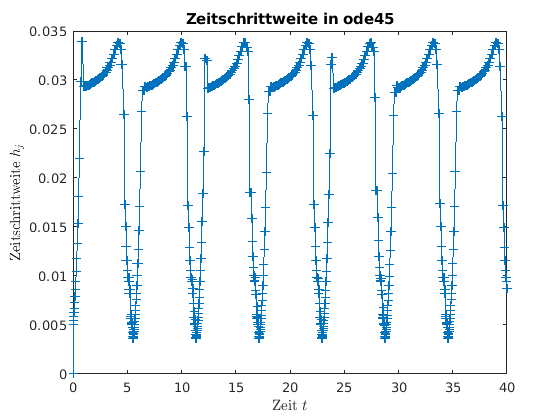

figure(2);
plotSchrittweite(t);

# Aktivität:

Variieren Sie den Parameterwert $\mu \in [1,40]$ und die angestrebte relative Toleranz.

Beobachten Sie die Anpassung der Zeitschrittweite an das Verhalten der Lösung und an die angestrebte Toleranz.

 function plotSchrittweite(t)
     Zeitschritt= diff(t); % berechnet [t(2)-t(1), ..., t(n)-t(n-1)]
     Zeitschritt= [0; Zeitschritt]; % damit t und Zeitschritt dieselbe Groesse haben
     plot(t,Zeitschritt,'-+');
     title('Zeitschrittweite in ode45');
     xlabel('Zeit $t$','Interpreter','latex');
     ylabel('Zeitschrittweite $h_j$','Interpreter','latex');
 end

function fout= f(t,y) % wertet die rechte Seite der DGLn aus
    global mu;
    fout=[y(2); mu*(1 - y(1)^2)*y(2) - y(1)];
end